# Topology Optimization using LSM

In this example, we optimize for the nonlinear coefficient $\gamma$ of the reduced dynamics on a 3rd-order expansion of the **Lyapunov Subcenter Manifold** (LSM) using **Topology Optimization** (TO). The sensitivities are computed using the **adjoint method**, and the optimization is solved using the **Method of Moving Asymptotes** (MMA).

References:

- *Topology Optimization*: Bendsoe, M. P., & Sigmund, O., "[Topology optimization: theory, methods, and applications](https://doi.org/10.1007/978-3-662-05086-6)", Springer Berlin, Heidelberg, 2013.

- *Method of Moving Asymptotes*: Svanberg, K., "[The method of moving asymptotes - a new method for structural optimization](https://doi.org/10.1002/nme.1620240207)", International journal for numerical methods in engineering, 1987.

- *LSM Optimization*: Pozzi M., Marconi J., Jain S. & Braghin F., "[Backbone curve tailoring via Lyapunov subcenter manifold optimization](https://doi.org/10.1007/s11071-024-09881-5)", Nonlinear Dynamics, 2024.

- *Adjoint formulation*: Mingwu Li, "[Explicit sensitivity analysis of spectral submanifolds of mechanical systems](https://doi.org/10.1007/s11071-024-09947-4)", Nonlinear Dynamics, 2024.

clear; clc; close all;

addpath TO-LSM-functions

## Problem settings

The system we consider is a **MBB beam** with a fixed proof mass (black) on the side of the rollers.

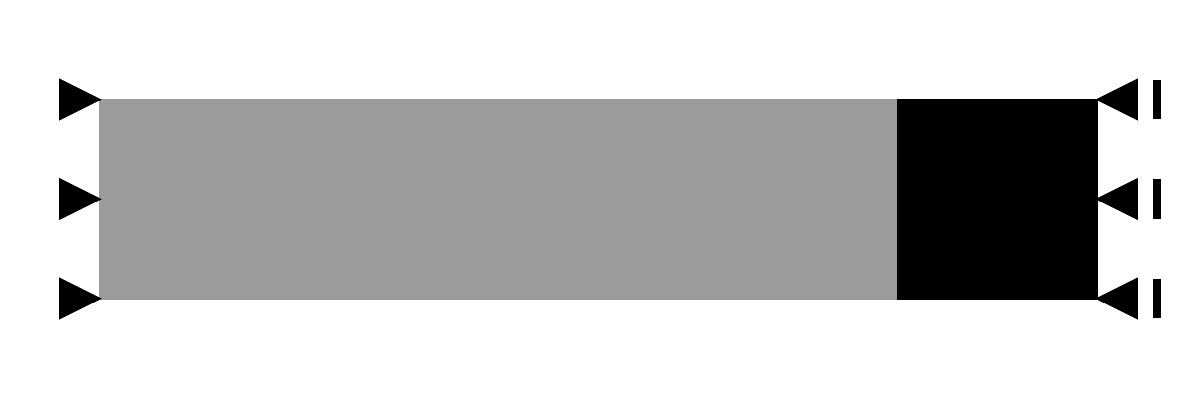

The design domain ($500\,\mathrm{\mu m} \times 100\,\mathrm{\mu m}$) is discretized using a $100 \times 20$ structured grid made of bi-linear squared elements (Quad4).

All the elements of the design domain (grey) are inizialized with density $0.5$, while the elements of the proof mass (black) have density $1.0$ that remains constant througout the optimization.

A constant thickness of $24\,\mathrm{\mu m}$ is used, and the plane-stress approximation is applied.

The selected material is Polysilicon, which is characterized by Young's modulus $148\,\mathrm{GPa}$, Poisson's coefficient $0.23$, and density $2330\,\mathrm{kg/m^3}$.

At each iteration, the Modal Assurance Criterion (MAC) is used to neglect artificial modes and to deal with modes switching.

## Finite element model

% Material
E   = 148e9;    % Young's modulus [Pa]
rho = 2330e-6;  % density [ng/um^3]
nu  = 0.23;     % Poisson's ratio [-]

thickness = 24; % beam's out-of-plane thickness [um]

myMaterial = KirchoffMaterial();
set(myMaterial, 'YOUNGS_MODULUS', E, 'DENSITY', rho, 'POISSONS_RATIO', nu);
myMaterial.PLANE_STRESS = true;	% set "false" for plane_strain
myElementConstructor = @()Quad4Element(thickness, myMaterial);

% Design domain
lx = 500; ly = 100; % domain sizes [um]
nelx = 100; nely = 20;

[nodes, elements, nset] = mesh_2Drectangle(lx, ly, nelx, nely, 'QUAD4');

 Meshing 2000 elements (QUAD4) ...  0.01 s
  Nodes: 2121 
  Dofs:  4242 



% Mesh
myMesh = Mesh(nodes);
myMesh.create_elements_table(elements, myElementConstructor);
nDOFs = myMesh.nDOFs;

% Boundary conditions
myMesh.set_essential_boundary_condition(nset{1}, 1:2, 0);
myMesh.set_essential_boundary_condition(nset{3}, 1, 0);

% Assembly
myAssembly = Assembly(myMesh);

% Target DOF
targetNode = find_node(lx, ly/2, [], nodes);
targetDofs = get_index(targetNode, myMesh.nDOFPerNode);
targetDof = myAssembly.free2constrained_index(targetDofs(2));

## Topology optimization settings

% Filter parameters
radius = 4;
beta = 10; eta = 0.5;
dMin = 1e-6; p = 1;

% Elements centroid
coord = zeros(myMesh.nElements, 2);
for ii = 1:myMesh.nElements
    coord(ii, :) = mean(myMesh.Elements(ii).Object.nodes);
end

% Initialize object
to = TopologyOptimization([nelx, nely], coord, radius, beta, eta, dMin, p);

% Initial layout with uniform 0.5 density
to.initialize_density(0.5);

% Fix the proof mass with uniform 1.0 density
to.set_density_box([lx, ly], [0.2 * lx, 1e10], 1);

## Eigenfrequency optimization

The first optimization problem is a linear eigenfrequency maximization.

The optimization problem is stated as


$$\matrix{\max_{\mu} & \omega \cr \mathrm{s.t.} & A \leq A_{max}}$$


The target eigenfrequency is associated to the vertical displacement of the proof mass.

The maximum area is equal to the $50\%$ of the total design domain.

% Initialize optimizer
nConstraints = 1;
moveLimit = 0.01;
maxIter = 500;

% Optimize
solOmegaOpt = mbb_omega_topopt(myMesh, myAssembly, to, nConstraints, moveLimit, maxIter);


Iteration - Frequency - Area

   1       6.8794e+02       6.0965e-01
   2       6.7220e+02       5.7059e-01
   3       6.5428e+02       5.3223e-01
   4       6.5234e+02       5.0013e-01
   5       6.7622e+02       5.0029e-01
   6       6.9673e+02       5.0018e-01
   7       7.1403e+02       5.0014e-01
   8       7.2825e+02       5.0008e-01
   9       7.3964e+02       5.0002e-01
  10       7.4865e+02       4.9997e-01
  11       7.5582e+02       4.9997e-01
  12       7.6162e+02       4.9995e-01
  13       7.6613e+02       4.9996e-01
  14       7.7016e+02       4.9999e-01
  15       7.7320e+02       5.0004e-01
  16       7.7605e+02       5.0001e-01
  17       7.7824e+02       5.0003e-01
  18       7.8026e+02       4.9995e-01
  19       7.8196e+02       5.0000e-01
  20       7.8340e+02       4.9995e-01
  21       7.8468e+02       5.0001e-01
  22       7.8575e+02       4.9998e-01
  23       7.8677e+02       4.9999e-01
  24       7.8763e+02       4.9997e-01
  25       7.8844e+02       4.999

## Eigenfrequency optimization results

Optimization history.

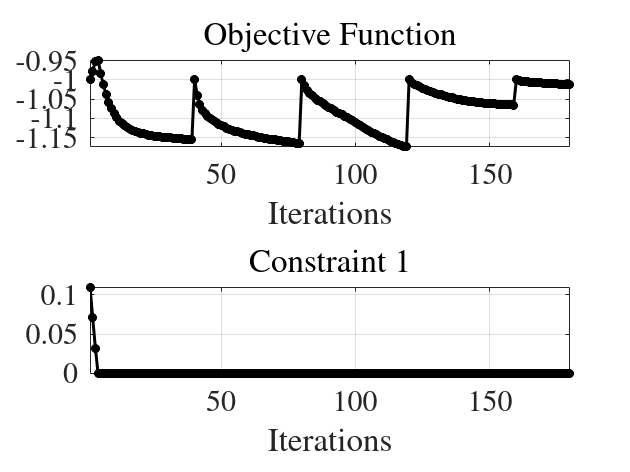

figure();
plot_history(solOmegaOpt.history);

Optimal layout.

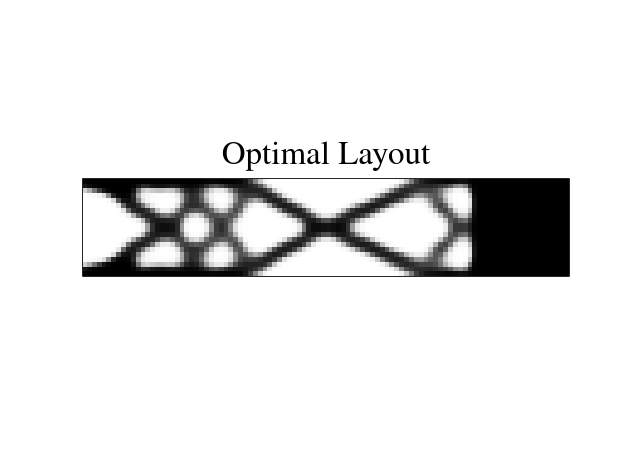

figure();
plot_layout([nelx, nely], solOmegaOpt.densHistory(:, end), to.mapFea2To);
title('Optimal Layout', 'Interpreter', 'latex');

The value of $\gamma$ is computed for the optimal layout.

% Optimal density field (SIMP)
densOpt = solOmegaOpt.densOpt;

% Assemble matrices and tensors
M = myAssembly.mass_matrix_uniform('weights', densOpt);
K = myAssembly.tangent_stiffness_and_force_uniform(zeros(nDOFs, 1), 'weights', densOpt);
T2 = myAssembly.tensor_uniform('T2', [nDOFs, nDOFs, nDOFs], [2, 3], 'weights', densOpt);
T3 = myAssembly.tensor_uniform('T3', [nDOFs, nDOFs, nDOFs, nDOFs], [2, 3, 4], 'weights', densOpt);

% Apply boundary conditions
Mc = myAssembly.constrain_matrix(M);
Kc = myAssembly.constrain_matrix(K);
T2c = myAssembly.constrain_tensor(T2);
T3c = myAssembly.constrain_tensor(T3);

% Compute gamma
g = gamma_value(Mc, Kc, T2c, T3c, solOmegaOpt.omega, solOmegaOpt.phi);
fprintf('\nGamma value: %.4e\n', g)


Gamma value: 1.3142e-04


Plot manifold and backbone curve.

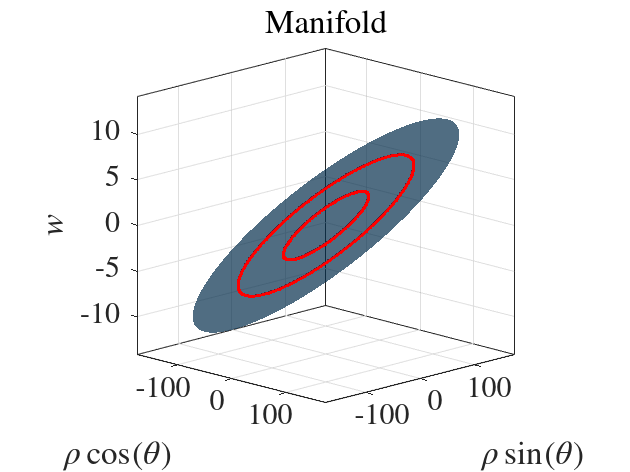

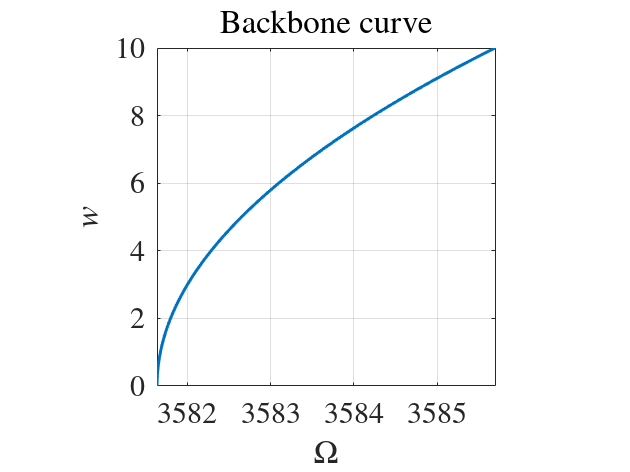

% Compute rho from the target physical displacement
wTarget = 10;
rhoTarget = compute_rho(wTarget, Mc, Kc, T2c, T3c, solOmegaOpt.omega, solOmegaOpt.phi, targetDof);
rho = linspace(0, rhoTarget, 51);

% Compute manifold and backbone
compute_manifold(Mc, Kc, T2c, T3c, solOmegaOpt.omega, solOmegaOpt.phi, rho, targetDof, true);

## $\gamma$ optimization

The first optimization problem is modified to add a constraint on the value of $\gamma$.

The optimization problem is stated as


$$\matrix{\max_{\mu} & \omega \cr \mathrm{s.t.} & A \leq A_{max} \cr & \gamma \leq \gamma_{max}}$$


The target eigenfrequency is associated to the vertical displacement of the proof mass.

The maximum area is equal to the $50\%$ of the total design domain, and the maximum value of $\gamma$ is $10^{-3}$. The constraint on $\gamma$ is used to enforce a softening behavior.

% Initialize optimizer
nConstraints = 2;
moveLimit = 0.01;
maxIter = 500;

% Optimize
solGammaOpt = mbb_gamma_topopt(myMesh, myAssembly, to, nConstraints, moveLimit, maxIter);


Iteration - Frequency - Gamma - Area

   1       5.7004e+02       1.3142e-04       4.9999e-01
   2       5.5843e+02       1.0219e-04       4.9600e-01
   3       5.4346e+02       7.3697e-05       4.9175e-01
   4       5.2571e+02       4.2680e-05       4.8713e-01
   5       5.0538e+02       2.3964e-06       4.8232e-01
   6       4.8215e+02      -5.8672e-05       4.7783e-01
   7       4.6158e+02      -1.5676e-04       4.7571e-01
   8       4.3925e+02      -2.9799e-04       4.7373e-01
   9       4.1944e+02      -5.2177e-04       4.7406e-01
  10       3.9452e+02      -8.9618e-04       4.7591e-01
  11       4.2218e+02      -9.0593e-04       4.8440e-01
  12       4.3640e+02      -1.0210e-03       4.9233e-01
  13       4.5762e+02      -1.0049e-03       4.9984e-01
  14       4.6970e+02      -9.9551e-04       4.9986e-01
  15       4.7831e+02      -1.0005e-03       4.9988e-01
  16       4.8516e+02      -1.0018e-03       4.9990e-01
  17       4.9064e+02      -9.9649e-04       4.9992e-01
  18     

## $\gamma$ optimization results

Optimization history.

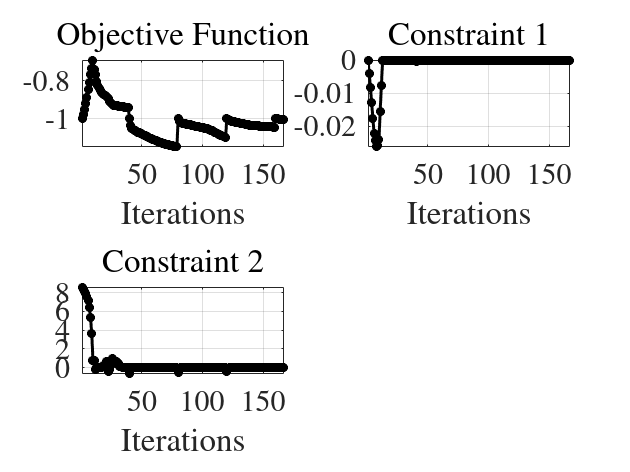

figure();
plot_history(solGammaOpt.history);

Optimal layout.

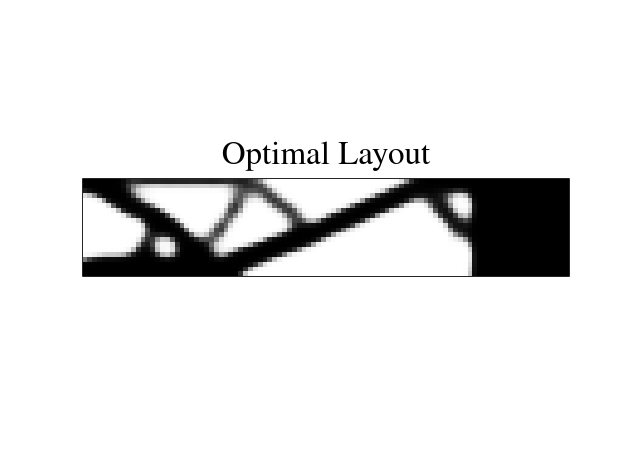

figure();
plot_layout([nelx, nely], solGammaOpt.densHistory(:, end), to.mapFea2To);
title('Optimal Layout', 'Interpreter', 'latex');

The value of $\gamma$ is computed for the optimal layout.

% Optimal density field (SIMP)
densOpt = solGammaOpt.densOpt;

% Assemble matrices and tensors
M = myAssembly.mass_matrix_uniform('weights', densOpt);
K = myAssembly.tangent_stiffness_and_force_uniform(zeros(nDOFs, 1), 'weights', densOpt);
T2 = myAssembly.tensor_uniform('T2', [nDOFs, nDOFs, nDOFs], [2, 3], 'weights', densOpt);
T3 = myAssembly.tensor_uniform('T3', [nDOFs, nDOFs, nDOFs, nDOFs], [2, 3, 4], 'weights', densOpt);

% Apply boundary conditions
Mc = myAssembly.constrain_matrix(M);
Kc = myAssembly.constrain_matrix(K);
T2c = myAssembly.constrain_tensor(T2);
T3c = myAssembly.constrain_tensor(T3);

% Compute gamma
g = gamma_value(Mc, Kc, T2c, T3c, solGammaOpt.omega, solGammaOpt.phi);
fprintf('\nGamma value: %.4e\n', g)


Gamma value: -1.0003e-03


Plot manifold and backbone curve.

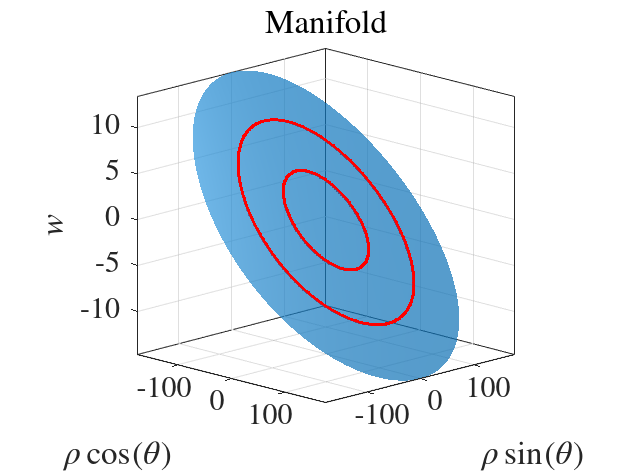

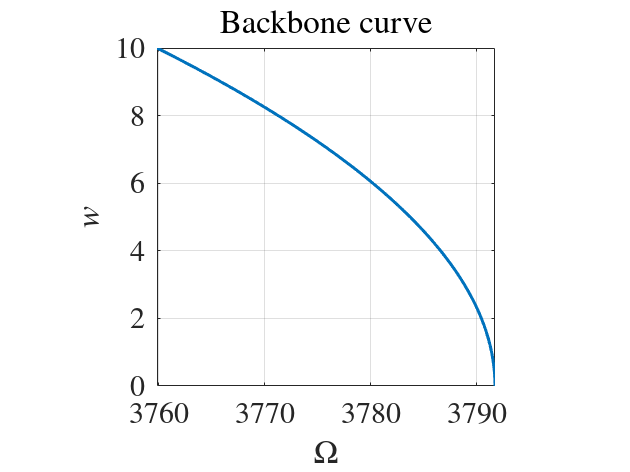

% Compute rho from the target physical displacement
wTarget = 10;
rhoTarget = compute_rho(wTarget, Mc, Kc, T2c, T3c, solGammaOpt.omega, solGammaOpt.phi, targetDof);
rho = linspace(0, rhoTarget, 51);

% Compute manifold and backbone
compute_manifold(Mc, Kc, T2c, T3c, solGammaOpt.omega, solGammaOpt.phi, rho, targetDof, true);